# Midterm Exam (Take-Home)

**2019020553 이재승**

## Use Histogram to show the distribution of each Generated Random Number

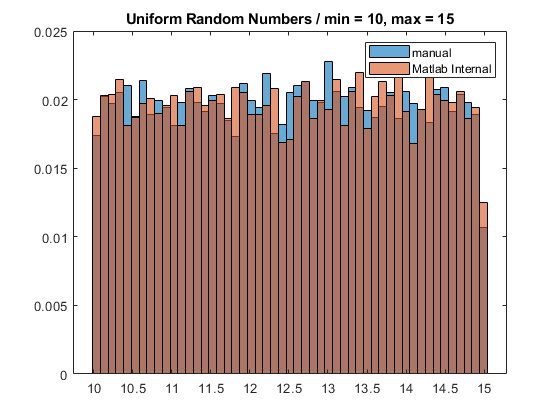

clearvars
close all

Totals = 10000;
NumBins = 51;

 
% Uniform Random Numbers
a = 10;
b = 15;
uni_out = genuniform(Totals, a, b);
histogram(uni_out, NumBins, 'Normalization', 'probability');
hold on

uni_out2 = unifrnd(a, b, 1, Totals);
histogram(uni_out2, NumBins, 'Normalization', 'probability');

title(['Uniform Random Numbers / min = ',num2str(a) ,', max = ', num2str(b)])
legend('manual', 'Matlab Internal')
hold off

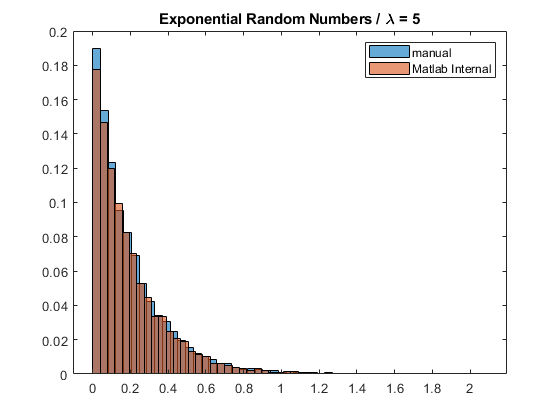


% Exponential Random Numbers
lambda = 5;
exp_out = genexponent(Totals, lambda);
histogram(exp_out, NumBins, 'Normalization', 'probability');
hold on

exp_out2 = exprnd(1/lambda, 1, Totals);
histogram(exp_out2, NumBins, 'Normalization','probability');

title(['Exponential Random Numbers / \lambda = ', num2str(lambda)])
legend('manual', 'Matlab Internal')
hold off

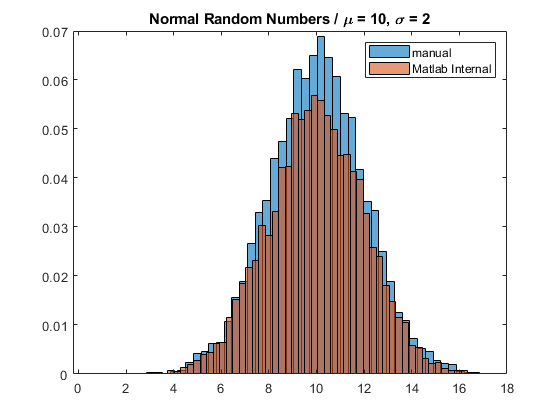


% Normal Random Numbers
mu = 10;
sigma = 2;
norm_out = gennormal(Totals, mu, sigma);
histogram(norm_out, NumBins, 'Normalization', 'probability');

hold on
norm_out2 = normrnd(mu, sigma, 1, Totals);
histogram(norm_out2, NumBins, 'Normalization', 'probability');

title(['Normal Random Numbers / \mu = ', num2str(mu), ', \sigma = ', num2str(sigma)])
legend('manual', 'Matlab Internal')
hold off

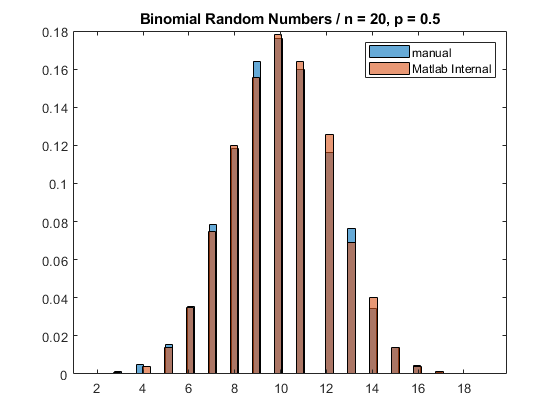



% Binomial Random Numbers
n = 20;
p = 0.5;
binorm_out = genbinomial(Totals, n, p);
binorm_out2 = binornd(n, p, 1, Totals);

histogram(binorm_out, NumBins, 'Normalization', 'probability');
hold on
histogram(binorm_out2, NumBins, "Normalization", 'probability');

title(['Binomial Random Numbers / n = ', num2str(n), ', p = ', num2str(p)])
legend('manual', 'Matlab Internal')
hold off

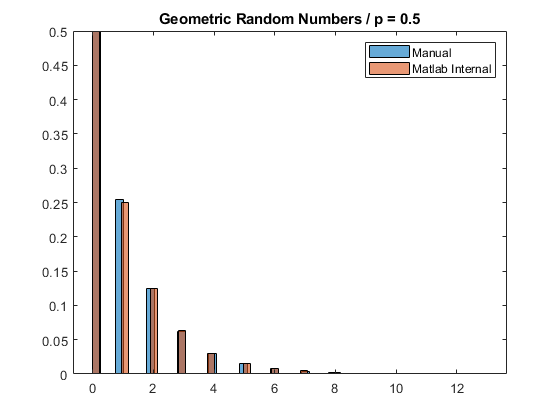



% Geometric Random Numbers
p2 = 0.5;
geo_out = gengeometric(Totals, p2);
histogram(geo_out, NumBins, 'Normalization', 'probability');
hold on

geo_out2 = geornd(p2, 1, Totals);
histogram(geo_out2, NumBins, 'Normalization', 'probability');
title(['Geometric Random Numbers / p = ', num2str(p2)])
legend("Manual", "Matlab Internal")
hold off

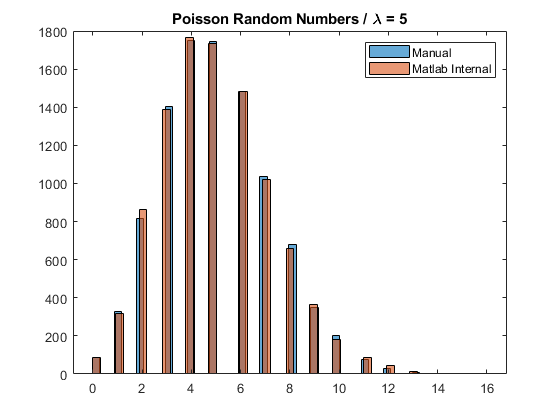


% Poisson Random Numbers
lambda2 = 5;
poi_out = genpoisson(Totals, lambda2);
histogram(poi_out, NumBins, 'Normalization', 'count');

hold on
poi_out2 = poissrnd(5, 1, Totals);
histogram(poi_out2, NumBins, 'Normalization', 'count');

title(['Poisson Random Numbers / \lambda = ', num2str(lambda2)])
legend("Manual", "Matlab Internal")
hold off

## Several types of Random Number Generation Function

function X = genuniform(N, a, b)
% Uniform Random Numbers

X = a + (b-a)*rand(N, 1);
end

function X = genexponent(N, lambda)
% Exponential Random Numbers

U = rand(N, 1);
X = -log(1-U)/lambda;
end

function [X1, X2] = gennormal(N, mu, sigma)
% Normal Random Numbers

U = rand(N, 1);
Z = sqrt(-2*sigma^2*(log(1-U)));
U2 = rand(N, 1);
X1 = mu + Z.*cos(2*pi*U2);
X2 = mu + Z.*sin(2*pi*U2);
end

function X = genbinomial(N, n, p)
% Binomial Random Numbers

X = sum(rand([1,N,n]) <= p, 3);
end

function X = gengeometric(N, p)
% Geometric Random Numbers

u = rand(1, N);
X = floor(abs(log(u)/log(1-p)));
end

function X = genpoisson(N, lambda)
% Poisson Random Numbers

X = zeros(1, N);
for i=1:N
    k=0; p=1;
    
    p = p*rand;
    while p >= exp(-lambda)
        k = k+1;
        p = p*rand;        
    end
        X(i)=k;
        
end

end